# 演習8-1 LU分解法

••MATLABのLU分解で線形方程式を解く


•行列AをLU分解．L，U，Eを表示


•LとUの積がAに一致することを確認


$$\left\lbrack \begin{array}{ccc}
2 & 3 & 4\\
1 & 2 & 3\\
1 & 1 & 3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
9\\
6\\
5
\end{array}\right\rbrack$$



$$\textrm{Ax}=b$$


A=[4 2 0 0 0;5 0 1 0 0;2 6 2 2 3;2 2 5 5 6];
b=[3;11;-4;12];                 % 右辺ベクトルの定義
format shortEng             % 表示の書式指定
% LU分解の呼び出し
% E　は置換行列（この例では単位行列なので無視）
[L,U]= lu(A)

L =      1.0000e+000     0.0000e+000     0.0000e+000
   500.0000e-003     1.0000e+000     0.0000e+000
   500.0000e-003    -1.0000e+000     1.0000e+000


U =      2.0000e+000     3.0000e+000     4.0000e+000
     0.0000e+000   500.0000e-003     1.0000e+000
     0.0000e+000     0.0000e+000     2.0000e+000


[L,U,E]= lu(A)

L =      1.0000e+000     0.0000e+000     0.0000e+000
   500.0000e-003     1.0000e+000     0.0000e+000
   500.0000e-003    -1.0000e+000     1.0000e+000


U =      2.0000e+000     3.0000e+000     4.0000e+000
     0.0000e+000   500.0000e-003     1.0000e+000
     0.0000e+000     0.0000e+000     2.0000e+000


E =      1.0000e+000     0.0000e+000     0.0000e+000
     0.0000e+000     1.0000e+000     0.0000e+000
     0.0000e+000     0.0000e+000     1.0000e+000


L*U

ans =      2.0000e+000     3.0000e+000     4.0000e+000
     1.0000e+000     2.0000e+000     3.0000e+000
     1.0000e+000     1.0000e+000     3.0000e+000


c=L\b

c =      9.0000e+000
     1.5000e+000
     2.0000e+000


x=U\c

x =      1.0000e+000
     1.0000e+000
     1.0000e+000


# 演習8-2 LU分解と逆行列の計算時間の比較

•LU分解と逆行列の計算時間を比較する


%　使用する次元数のリストdim
dim=[500,1000,1500,2000,2500,45000];
Inv_time=zeros(1,size(dim,2));
LU_time=zeros(1,size(dim,2));

% 計算の反復回数（時間計測の安定化のため）
ncount=1;
for k=1:size(dim,2)
  % 次元数 n
  n=dim(k) ;
  % 行列の初期化
  A=zeros(n,n);
  AI=zeros(n,n);
  L=zeros(n,n);
  U=zeros(n,n);
  E=zeros(n,n);

  % フランク行列の定義
for i=1:n
  for j=1:n
    A(i,j)=n-max(i,j)+1;
  end
end

% 次元数nの表示
  n
  disp('timer start')
% 逆行列
% 時間計測開始
tic
  for count=1:ncount
  AI=inv(A);
  end
%　時間計測終了と記録
Inv_time(k)=toc/ncount;
%　LU分解
% 時間計測開始
tic;
for count=1:ncount
  [L,U,E]=lu(A);
end
%　時間計測終了と記録
LU_time(k)=toc/ncount;
end

n =    500.0000e+000


timer start


n =      1.0000e+003


timer start


n =      1.5000e+003


timer start


n =      2.0000e+003


timer start


n =      2.5000e+003


timer start


n =     45.0000e+003


timer start


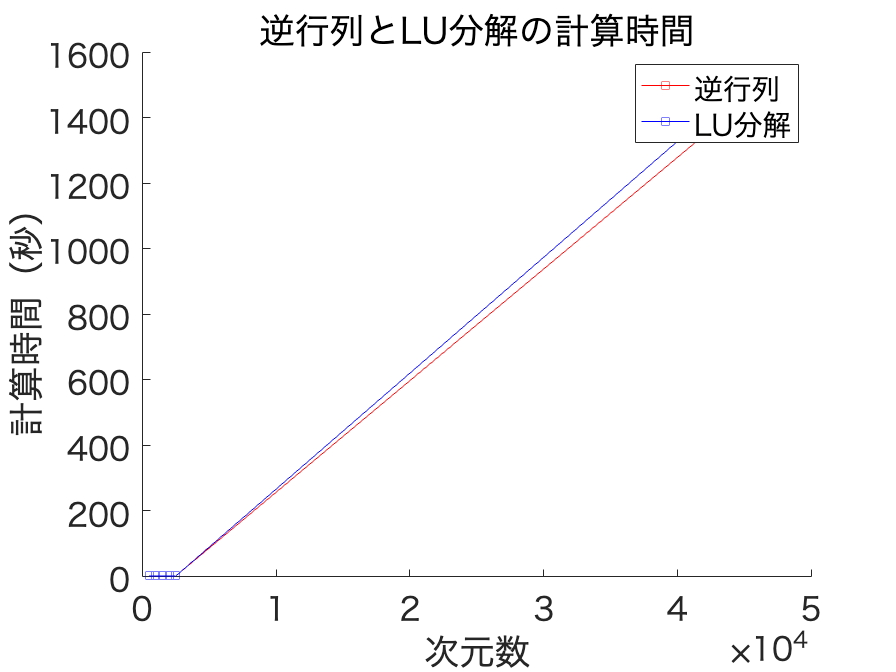


% グラフ作成
clf
hold on;
plot(dim, Inv_time, 'r-s'); % 逆行列は赤色(r)
plot(dim, LU_time, 'b-s'); % LU分解は青色(b)
ax=gca;             % グラフハンドルの取得
ax.FontSize =20;
ax.YScale='linear'; % y軸スケールの設定
ax.XScale='linear';    % x軸対数スケールの設定
xlabel('次元数'); 
ylabel('計算時間（秒）');
legend('逆行列','LU分解');
title('逆行列とLU分解の計算時間')
hold off;

# 演習8-3 フランク行列と逆行列の表示

%　使用する次元数
n=100

n =    100.0000e+000


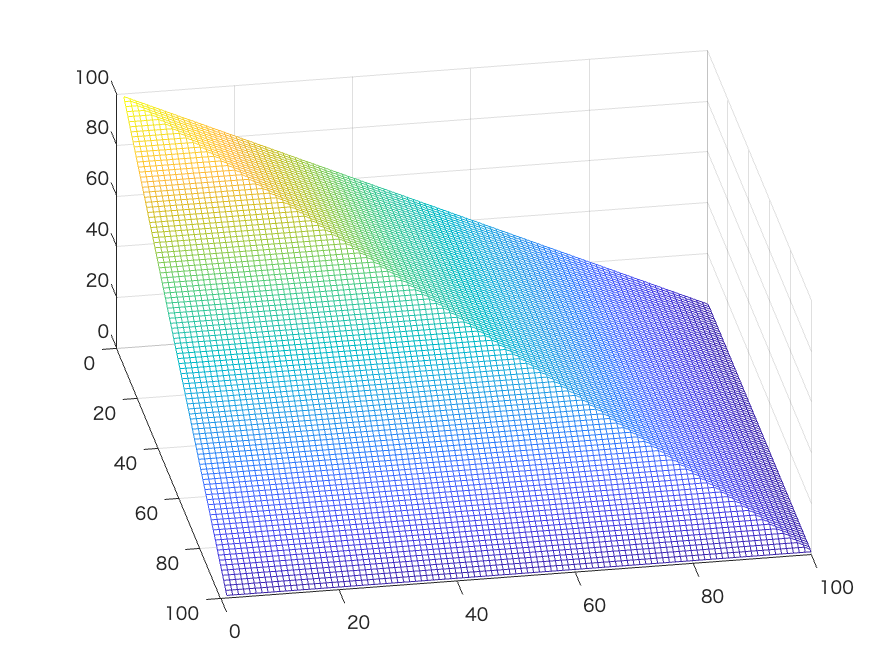

A=zeros(n,n);
AI=zeros(n,n);
L=zeros(n,n);
U=zeros(n,n);
E=zeros(n,n);

% フランク行列の定義
for i=1:n
  for j=1:n
    A(i,j)=n-max(i,j)+1;
  end
end

% フランク行列の逆行列
AI=inv(A);

% グラフ作成
clf

mesh(A);
view([80 45])

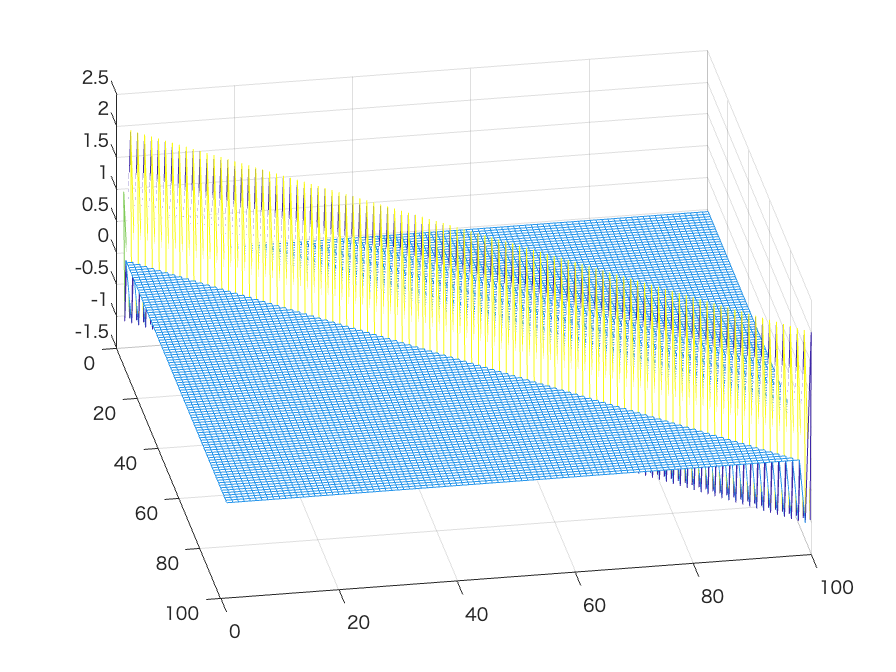

mesh(AI);
view([80 45])